
%% ex3_koopman_learning_from_lorenz_data_demo.m
% Recitation Demo (Complex Systems): Koopman operator / Koopman generator
% viewpoint for learning dynamics from data (using the Lorenz system).
%
% What we do (in a teaching-friendly way):
%   1) Generate data from the Lorenz ODE.
%   2) Choose a finite dictionary of observables (polynomials up to degree 2).
%   3) Estimate a linear operator on observables from data:
%        - Discrete-time Koopman:  Phi(x_{k+1}) ~ K Phi(x_k)
%        - Continuous-time generator: d/dt Phi(x(t)) ~ L Phi(x(t))
%   4) Interpret the learned generator restricted to coordinate functions
%      as an estimated vector field (i.e., an "equation from data").
%
% Pedagogical punchline:
%   The Lorenz vector field is quadratic. A quadratic dictionary is enough
%   to recover (approximately) the true coefficients from clean data.
%
% -------------------------------------------------------------------------

clear; close all; clc;

%% --------------------------- USER CONTROLS -----------------------------
Ptrue.sigma = 10;
Ptrue.rho   = 28;
Ptrue.beta  = 8/3;

dt   = 0.01;         % sampling time step
Tend = 40;           % seconds (Lorenz time is dimensionless)
tgrid = 0:dt:Tend;

x0 = [1; 1; 1];

addNoise = false;
noiseStd = 0.0;      % e.g. 0.05 if you want to discuss noise sensitivity

ridge = 1e-10;       % small Tikhonov regularization for least squares stability

%% --------------------------- GENERATE DATA -----------------------------
opts = odeset('RelTol',1e-10,'AbsTol',1e-12,'MaxStep',0.02);
fprintf('Generating Lorenz training data on uniform grid dt=%.4f...\n', dt);

Generating Lorenz training data on uniform grid dt=0.0100...


[t, X] = ode45(@(t,x) lorenz_rhs(t,x,Ptrue), tgrid, x0, opts);

% Ensure outputs are exactly on grid (ode45 returns at specified tgrid)
X = X.';                      % make it 3 x N for linear-algebra convenience
N = size(X,2);

if addNoise
    X = X + noiseStd*randn(size(X));
end

x = X(1,:); y = X(2,:); z = X(3,:);

%% ------------------- BUILD DICTIONARY Phi(x) ---------------------------
% Dictionary of observables (polynomials up to degree 2):
%   Phi = [1, x, y, z, x^2, y^2, z^2, xy, xz, yz]^T
%
% For Lorenz (quadratic vector field), this dictionary is natural.

Phi = library_poly2(x,y,z);         % p x N
p = size(Phi,1);

%% ---------------- ESTIMATE CONTINUOUS-TIME GENERATOR (via derivatives) -
% Infinitesimal generator L acts on observables g(x):
%   (Lg)(x) = d/dt g(x(t)) |_{x(t)=x}
%           = \nabla g(x) · f(x)
%
% With data, approximate:
%   d/dt Phi(x(t_k))  ~  L * Phi(x(t_k))
%
% Here we only need the first three rows corresponding to the coordinate
% observables g1=x, g2=y, g3=z, because:
%   dx/dt = L(x),  dy/dt = L(y),  dz/dt = L(z)
%
% We estimate Xdot by finite differences on the uniform grid.

Xdot = finite_difference_derivative(X, dt);     % 3 x N

% Solve least squares for B such that:
%   Xdot ~ B * Phi
% B is 3 x p (coefficients of library in each component equation).

G = Phi*Phi.' + ridge*eye(p);
B = (Xdot*Phi.') / G;

fprintf('\nEstimated coefficients for vector field using generator regression:\n');


Estimated coefficients for vector field using generator regression:


print_lorenz_library_coeffs(B);

  Library order: [1 x y z x^2 y^2 z^2 xy xz yz ]

  xdot coefficients:
    1   : +0.061459
    x   : -10.075183
    y   : +10.051343
    z   : -0.006478
    xz  : +0.002955
    yz  : -0.002372

  ydot coefficients:
    1   : +0.147622
    x   : +27.775670
    y   : -0.940079
    z   : -0.017099
    x^2 : -0.001427
    xy  : +0.001094
    xz  : -0.993607

  zdot coefficients:
    1   : -0.278220
    x   : -0.039504
    y   : +0.025414
    z   : -2.588851
    x^2 : +0.025372
    y^2 : +0.006724
    z^2 : -0.003006
    xy  : +0.971561
    xz  : +0.001090



%% Compare to true coefficients (in this dictionary order)
Btrue = true_lorenz_coeffs_in_library(Ptrue);
err = norm(B - Btrue, 'fro')/norm(Btrue,'fro');
fprintf('Relative Frobenius error vs true coefficients: %.2e\n', err);

Relative Frobenius error vs true coefficients: 1.33e-02


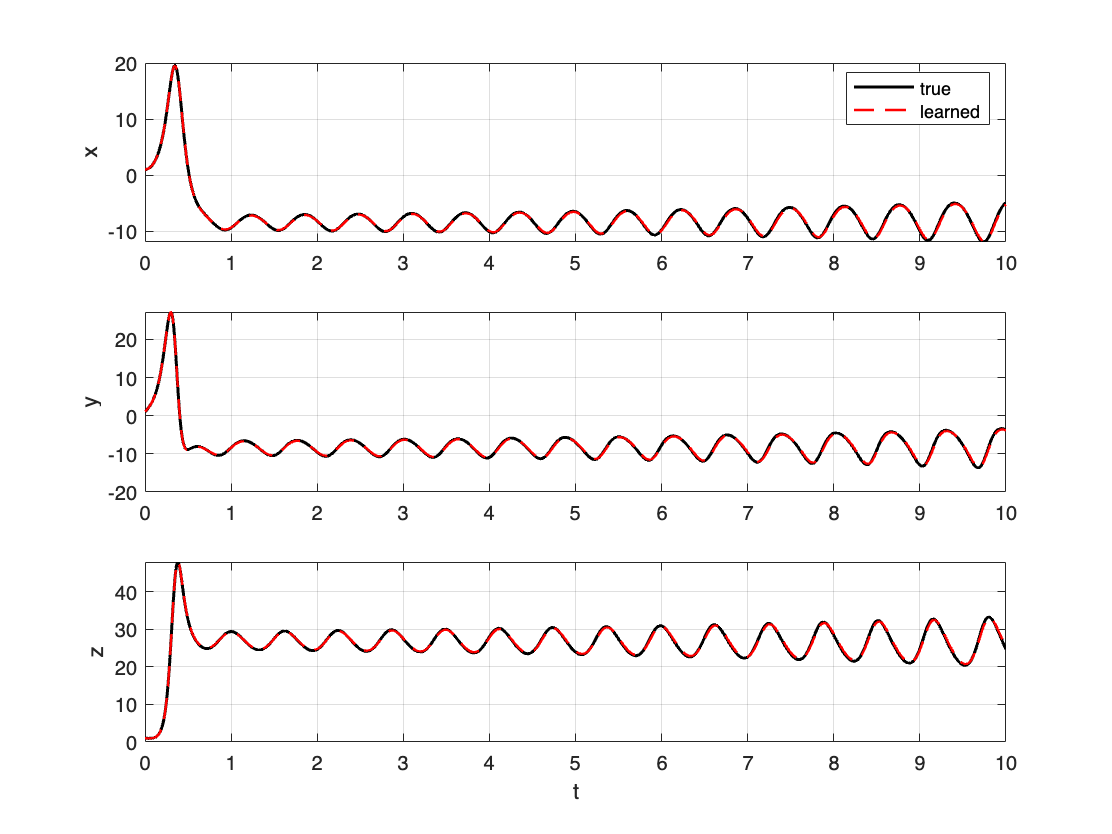


%% -------------- TEST: SIMULATE THE LEARNED ODE AND COMPARE -------------
% Learned ODE:
%   d/dt [x;y;z] = B * Phi(x,y,z)
%
% Integrate from same initial condition and compare trajectories
% (in chaotic systems, long-term trajectory matching is impossible; focus on
%  short-time agreement and statistical structure).

Ttest = 10;                       % short horizon for trajectory comparison
tgrid_test = 0:dt:Ttest;

opts2 = odeset('RelTol',1e-10,'AbsTol',1e-12,'MaxStep',0.02);
[t_true, X_true] = ode45(@(t,x) lorenz_rhs(t,x,Ptrue), tgrid_test, x0, opts2);
[t_hat,  X_hat]  = ode45(@(t,x) learned_poly2_rhs(t,x,B), tgrid_test, x0, opts2);

figure('Name','Short-horizon trajectory comparison (true vs learned)');
subplot(3,1,1); plot(t_true, X_true(:,1), 'k', 'LineWidth', 1.5); hold on;
              plot(t_hat,  X_hat(:,1),  'r--','LineWidth', 1.2);
              grid on; ylabel('x'); legend('true','learned');
subplot(3,1,2); plot(t_true, X_true(:,2), 'k', 'LineWidth', 1.5); hold on;
              plot(t_hat,  X_hat(:,2),  'r--','LineWidth', 1.2);
              grid on; ylabel('y');
subplot(3,1,3); plot(t_true, X_true(:,3), 'k', 'LineWidth', 1.5); hold on;
              plot(t_hat,  X_hat(:,3),  'r--','LineWidth', 1.2);
              grid on; ylabel('z'); xlabel('t');

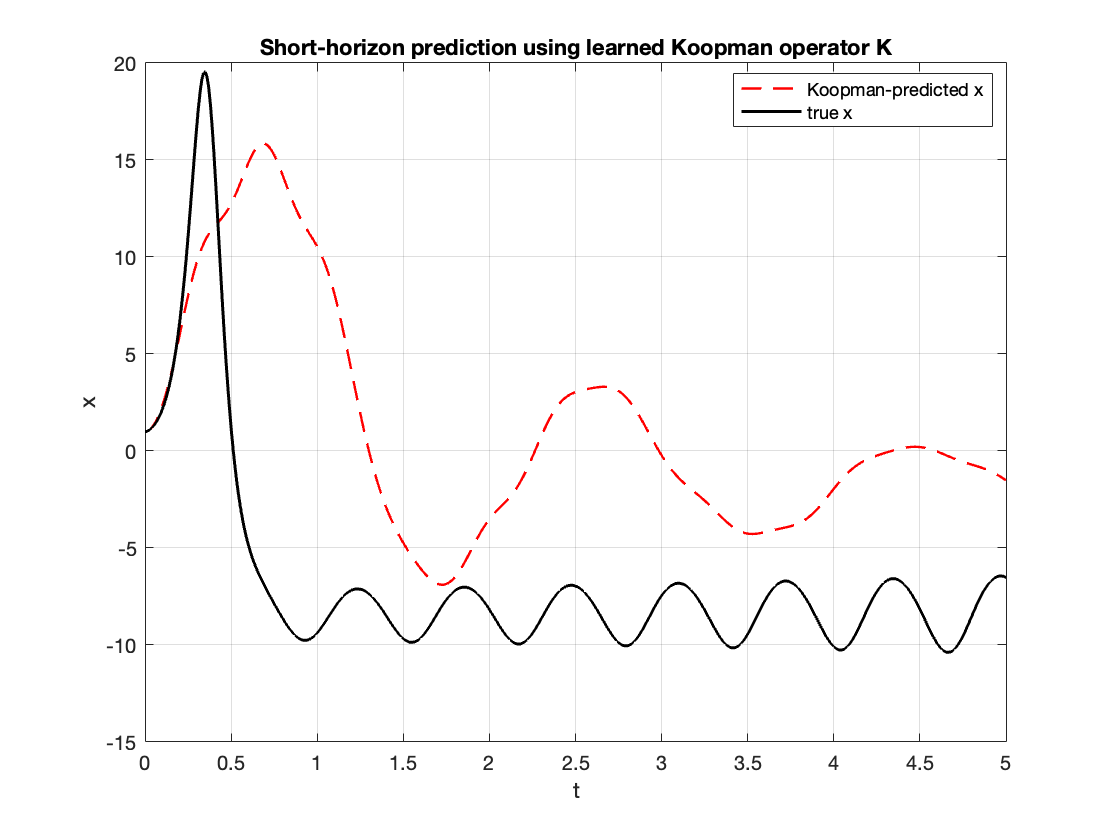


% [Insert slide image: short-horizon overlay true vs learned]

%% ----------- ESTIMATE DISCRETE-TIME KOOPMAN OPERATOR (EDMD) -------------
% EDMD estimate:
%   Phi_{k+1} ~ K * Phi_k
% where Phi_k = Phi(x_k).
%
% This is a discrete-time Koopman operator approximation on the chosen
% feature space.

Phi_now  = Phi(:,1:end-1);
Phi_next = Phi(:,2:end);

Gk = Phi_now*Phi_now.' + ridge*eye(p);
K = (Phi_next*Phi_now.') / Gk;

% Use K for prediction in feature space:
%   phi_{k+1} = K phi_k
% Reconstruct state using the coordinate entries of phi (x,y,z).

nStepsPred = round(5/dt);              % predict 5 time units
phi = Phi(:, 1);                       % start from first snapshot

Xpred = zeros(3, nStepsPred+1);
Xpred(:,1) = [phi(2); phi(3); phi(4)];

for k = 1:nStepsPred
    phi = K*phi;
    Xpred(:,k+1) = [phi(2); phi(3); phi(4)];
end

tPred = (0:nStepsPred)*dt;

figure('Name','Koopman (EDMD) prediction in lifted space');
plot(tPred, Xpred(1,:), 'r--', 'LineWidth', 1.2); hold on;
plot(t(1:nStepsPred+1), X(1,1:nStepsPred+1), 'k', 'LineWidth', 1.5);
grid on; xlabel('t'); ylabel('x');
legend('Koopman-predicted x','true x','Location','best');
title('Short-horizon prediction using learned Koopman operator K');


% Teaching note:
%   Even with a good dictionary, chaos limits long-term prediction.
%   But the Koopman model can still capture short-time evolution and
%   (with enough data) reproduce invariant statistics.

%% ---------------------- TEACHING CHECKLIST -----------------------------
% Minimal slide/figure set:
%   [Slide 1] Display recovered coefficients (table printout or screenshot).
%   [Slide 2] Short-horizon trajectory overlay (true vs learned).
%   [Slide 3] Koopman-prediction vs true for x(t) (short horizon).
%
% Discussion prompts:
%   - Why does a quadratic dictionary suffice for Lorenz?
%   - What breaks when data are noisy? (derivatives amplify noise)
%   - Why can't we predict chaos long-term, even with perfect equations?
%
% ------------------------------------------------------------------------
%% ----------------------------- FUNCTIONS --------------------------------

function dx = lorenz_rhs(~, x, P)
    dx = zeros(3,1);
    dx(1) = P.sigma*(x(2) - x(1));
    dx(2) = x(1)*(P.rho - x(3)) - x(2);
    dx(3) = x(1)*x(2) - P.beta*x(3);
end

function Phi = library_poly2(x,y,z)
    % x,y,z are row vectors 1xN
    Phi = [ones(size(x));
           x;
           y;
           z;
           x.^2;
           y.^2;
           z.^2;
           x.*y;
           x.*z;
           y.*z];
end

function Xdot = finite_difference_derivative(X, dt)
    % X is 3 x N on uniform grid; return 3 x N derivatives.
    [d, N] = size(X);
    Xdot = zeros(d,N);

    % Central differences for interior points
    Xdot(:,2:N-1) = (X(:,3:N) - X(:,1:N-2)) / (2*dt);

    % One-sided differences for endpoints
    Xdot(:,1)   = (X(:,2) - X(:,1)) / dt;
    Xdot(:,N)   = (X(:,N) - X(:,N-1)) / dt;
end

function dx = learned_poly2_rhs(~, x, B)
    % Learned vector field: dx = B * Phi(x)
    xv = x(1); yv = x(2); zv = x(3);
    phi = [1;
           xv;
           yv;
           zv;
           xv^2;
           yv^2;
           zv^2;
           xv*yv;
           xv*zv;
           yv*zv];
    dx = B*phi;
end

function Btrue = true_lorenz_coeffs_in_library(P)
    % Dictionary order: [1, x, y, z, x^2, y^2, z^2, xy, xz, yz]
    Btrue = zeros(3,10);

    % xdot = sigma*(y-x)
    Btrue(1,2) = -P.sigma;   % x
    Btrue(1,3) =  P.sigma;   % y

    % ydot = rho*x - x*z - y
    Btrue(2,2) =  P.rho;     % x
    Btrue(2,3) = -1;         % y
    Btrue(2,9) = -1;         % xz

    % zdot = x*y - beta*z
    Btrue(3,4) = -P.beta;    % z
    Btrue(3,8) =  1;         % xy
end

function print_lorenz_library_coeffs(B)
    names = {'1','x','y','z','x^2','y^2','z^2','xy','xz','yz'};
    fprintf('  Library order: [');
    fprintf('%s ', names{:});
    fprintf(']\n');

    fprintf('\n  xdot coefficients:\n');
    print_row(B(1,:), names);

    fprintf('\n  ydot coefficients:\n');
    print_row(B(2,:), names);

    fprintf('\n  zdot coefficients:\n');
    print_row(B(3,:), names);
end

function print_row(row, names)
    % Print only "meaningful" coefficients (threshold)
    thr = 1e-3;
    for j = 1:length(row)
        if abs(row(j)) > thr
            fprintf('    %-3s : %+ .6f\n', names{j}, row(j));
        end
    end
end
